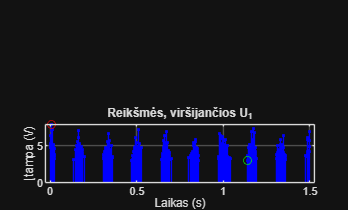

t = 0:0.001:1.5; 
A = 4.5;
f = 6;    
sigma = 1;  
U1 = 3;    
U2 = 1.5;  

s = A * cos(2 * pi * f * t);
n = sigma * randn(size(t));
s_paveiktas = s + n;

subplot(2, 1, 2);

t_virs = t(s_paveiktas > U1);
s_virs = s_paveiktas(s_paveiktas > U1);

stem(t_virs, s_virs, 'b.');
hold on;

didziausias = max(s_virs);
maziausias = min(s_virs);

t_did = t_virs(s_virs == didziausias);
t_maz = t_virs(s_virs == maziausias);

plot(t_did, didziausias, 'ro');
plot(t_maz, maziausias, 'go');
hold off;

title('Reikšmės, viršijančios U_1'); 
xlabel('Laikas (s)'); 
ylabel('Įtampa (V)');
grid on;